% Script pour exécuter l'analyse des EMG avec SPM1D et DTW
fprintf('Analyse des profils EMG moyens par muscle avec SPM1D et DTW\n');

Analyse des profils EMG moyens par muscle avec SPM1D et DTW


fprintf('======================================================\n\n');

addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Statistics\spm1dmatlab-master'))

% Demander si on souhaite utiliser l'alignement DTW
fprintf('Souhaitez-vous utiliser l''alignement DTW pour les courbes? (O/N): ');

Souhaitez-vous utiliser l'alignement DTW pour les courbes? (O/N): 

use_dtw_input = input('', 's');
use_dtw = lower(use_dtw_input) == 'o' || lower(use_dtw_input) == 'y' || isempty(use_dtw_input);

if use_dtw
    fprintf('Alignement DTW activé.\n');
else
    fprintf('Alignement DTW désactivé.\n');
end

Alignement DTW activé.



% Demander le nombre de fichiers à analyser
fprintf('\nCombien de fichiers souhaitez-vous analyser? (1-3): ');


Combien de fichiers souhaitez-vous analyser? (1-3): 

num_files = str2double(input('', 's'));

% Vérifier la validité du nombre
if isnan(num_files) || num_files < 1 || num_files > 3
    fprintf('Nombre invalide. Utilisation d''un seul fichier par défaut.\n');
    num_files = 1;
end

% Collecter les noms de fichiers
data_files = cell(num_files, 1);
for i = 1:num_files
    default_file = sprintf('combined_functional_data_for_spm1d_%d.mat', i);
    if i == 1
        default_file = 'combined_functional_data_for_spm1d.mat';
    end
    fprintf('\nFichier #%d:\n', i);
    fprintf('Quel fichier de données voulez-vous utiliser? (défaut: %s)\n', default_file);
    file_name = input('Nom du fichier (appuyez sur Entrée pour utiliser la valeur par défaut): ', 's');
    
    if isempty(file_name)
        file_name = default_file;
    end
    
    % Ajouter l'extension .mat si nécessaire
    if ~contains(file_name, '.mat')
        file_name = [file_name '.mat'];
    end
    data_files{i} = file_name;
end


Fichier #1:


Quel fichier de données voulez-vous utiliser? (défaut: combined_functional_data_for_spm1d.mat)



Fichier #2:


Quel fichier de données voulez-vous utiliser? (défaut: combined_functional_data_for_spm1d_2.mat)



Fichier #3:


Quel fichier de données voulez-vous utiliser? (défaut: combined_functional_data_for_spm1d_3.mat)


Chargement des données depuis combined_functional_data_for_spm1d_asympt.mat...
Chargement des données depuis combined_functional_data_for_spm1d_preOP.mat...
Chargement des données depuis combined_functional_data_for_spm1d_postOP.mat...


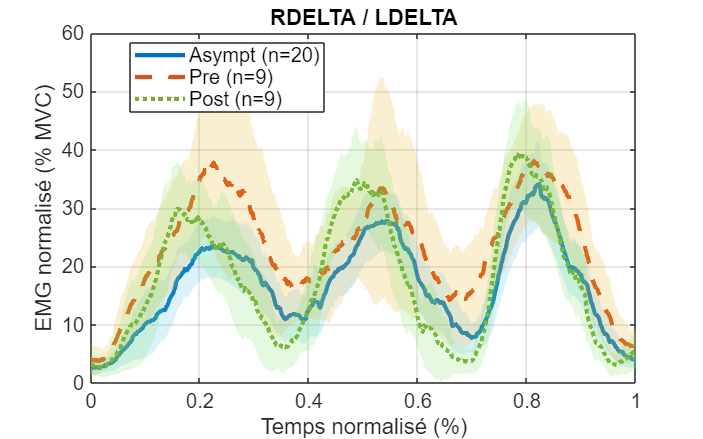

Alignement des courbes par DTW pour Asympt vs Pre...
Analyse SPM1D sur données alignées: Asympt vs Pre
Analyse SPM1D: Test indépendant pour Asympt vs Pre


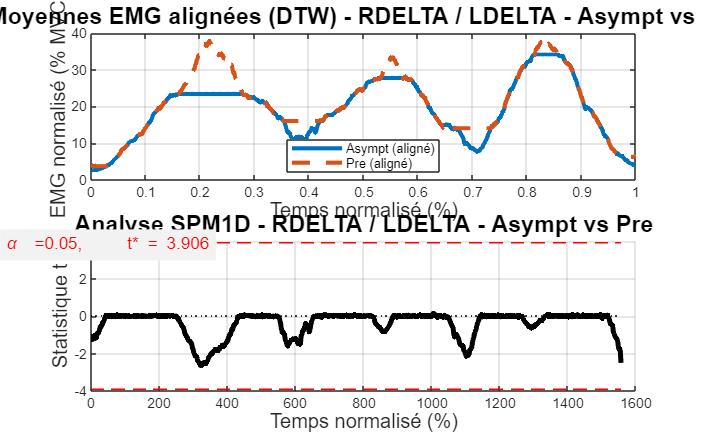

Alignement des courbes par DTW pour Asympt vs Post...
Analyse SPM1D sur données alignées: Asympt vs Post
Analyse SPM1D: Test indépendant pour Asympt vs Post


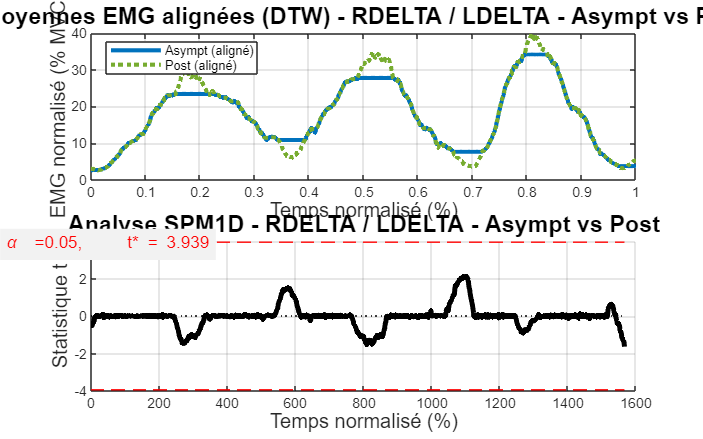

Alignement des courbes par DTW pour Pre vs Post...
Analyse SPM1D sur données alignées: Pre vs Post
Analyse SPM1D: Test apparié pour Pre vs Post


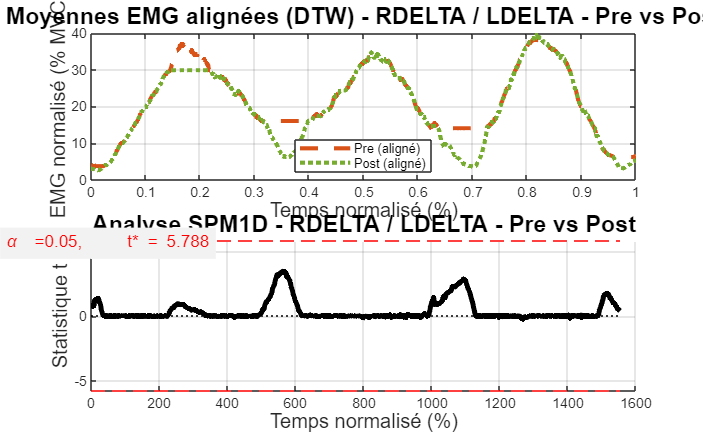

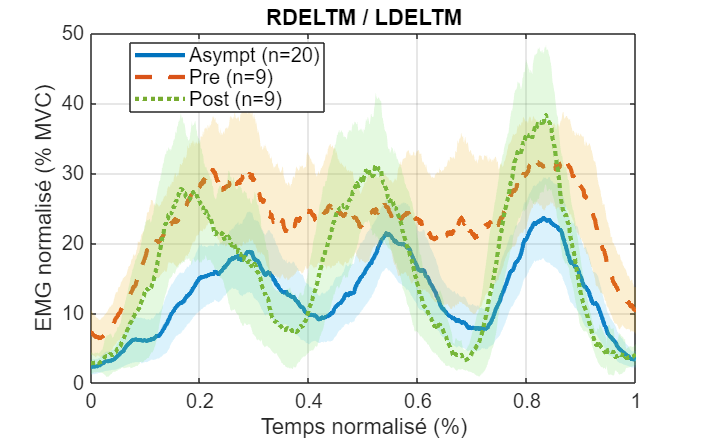

Alignement des courbes par DTW pour Asympt vs Pre...
Analyse SPM1D sur données alignées: Asympt vs Pre
Analyse SPM1D: Test indépendant pour Asympt vs Pre


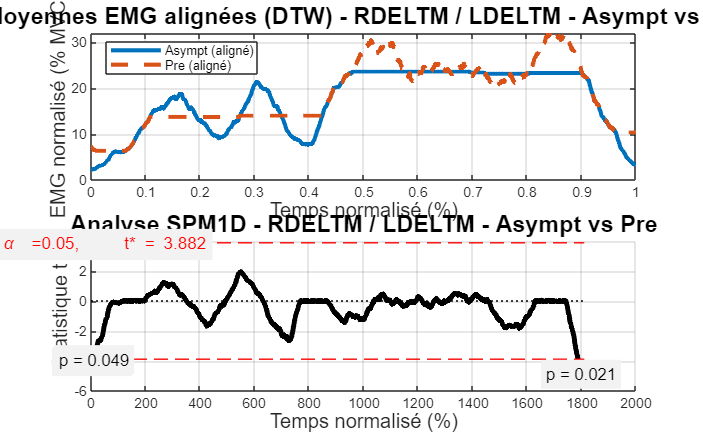

Alignement des courbes par DTW pour Asympt vs Post...
Analyse SPM1D sur données alignées: Asympt vs Post
Analyse SPM1D: Test indépendant pour Asympt vs Post


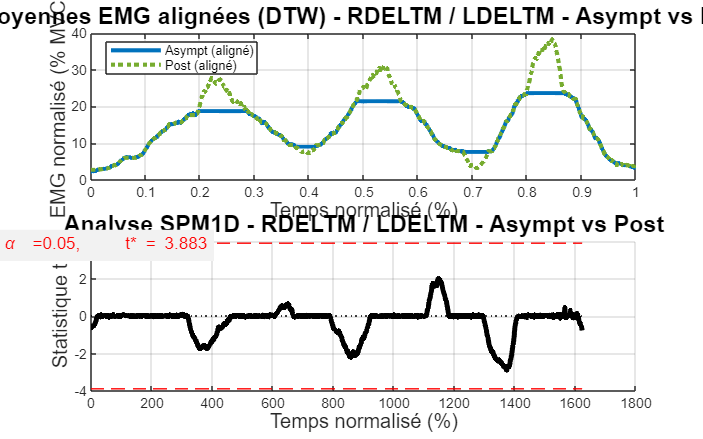

Alignement des courbes par DTW pour Pre vs Post...
Analyse SPM1D sur données alignées: Pre vs Post
Analyse SPM1D: Test apparié pour Pre vs Post


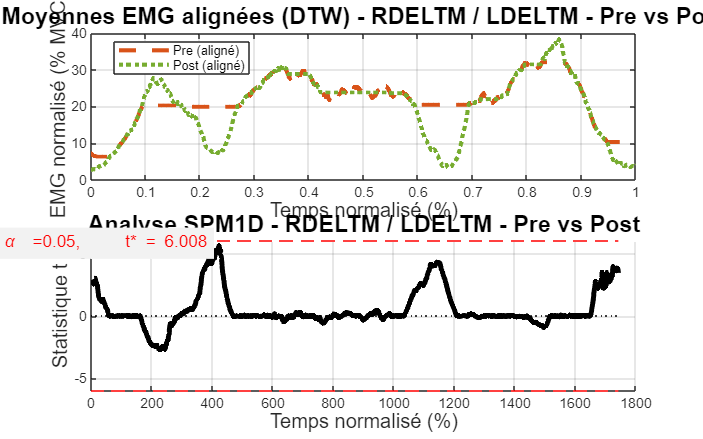

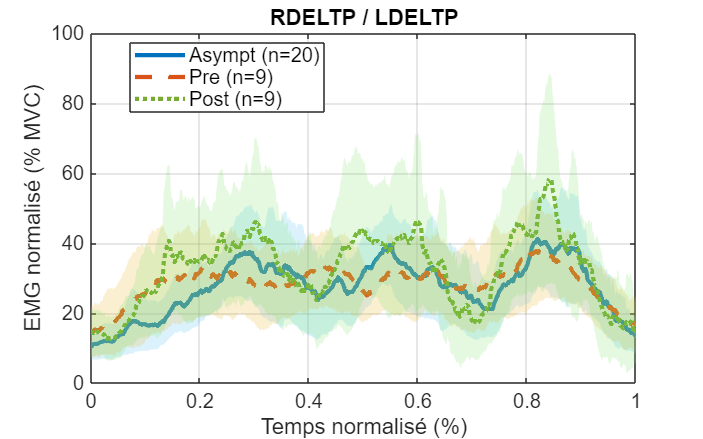

Alignement des courbes par DTW pour Asympt vs Pre...
Analyse SPM1D sur données alignées: Asympt vs Pre
Analyse SPM1D: Test indépendant pour Asympt vs Pre


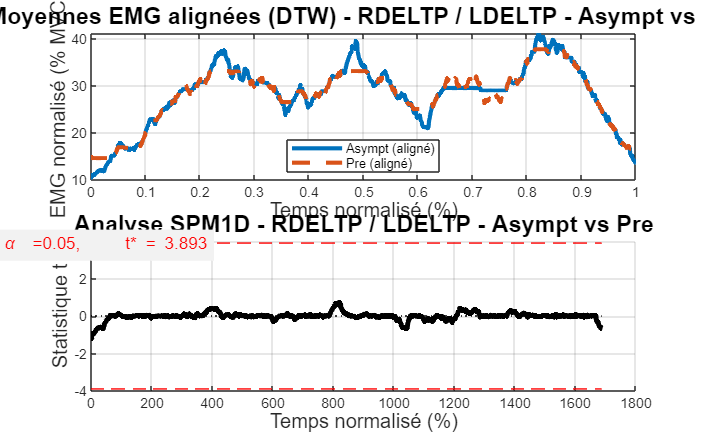

Alignement des courbes par DTW pour Asympt vs Post...
Analyse SPM1D sur données alignées: Asympt vs Post
Analyse SPM1D: Test indépendant pour Asympt vs Post


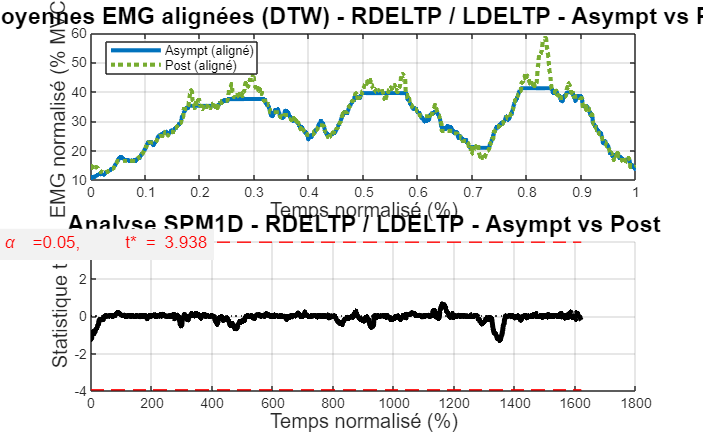

Alignement des courbes par DTW pour Pre vs Post...
Analyse SPM1D sur données alignées: Pre vs Post
Analyse SPM1D: Test apparié pour Pre vs Post


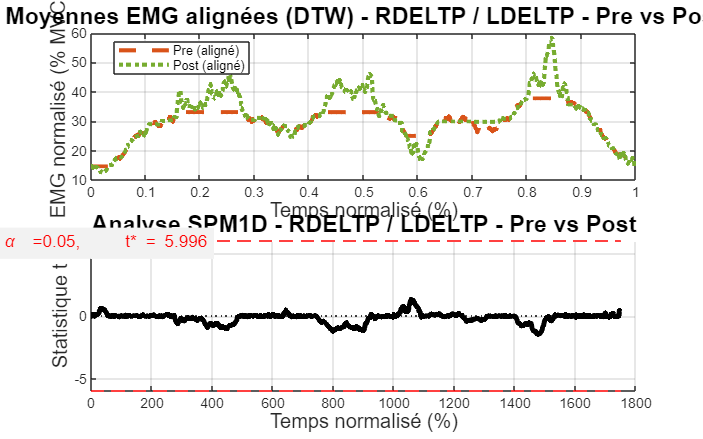

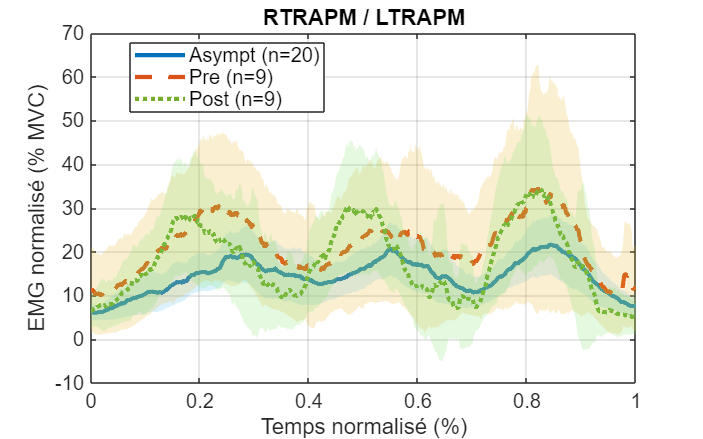

Alignement des courbes par DTW pour Asympt vs Pre...
Analyse SPM1D sur données alignées: Asympt vs Pre
Analyse SPM1D: Test indépendant pour Asympt vs Pre


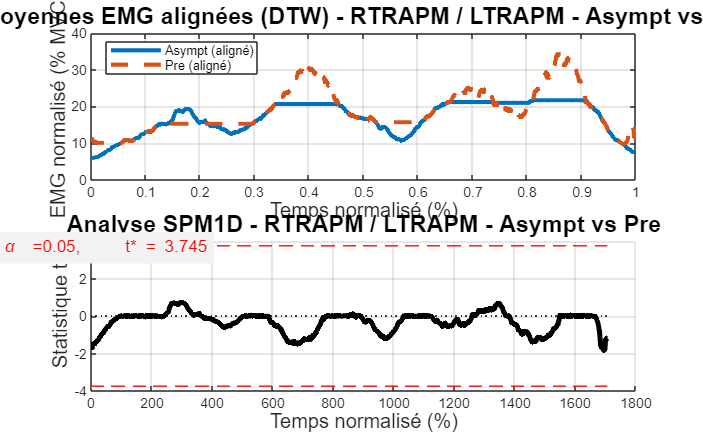

Alignement des courbes par DTW pour Asympt vs Post...
Analyse SPM1D sur données alignées: Asympt vs Post
Analyse SPM1D: Test indépendant pour Asympt vs Post


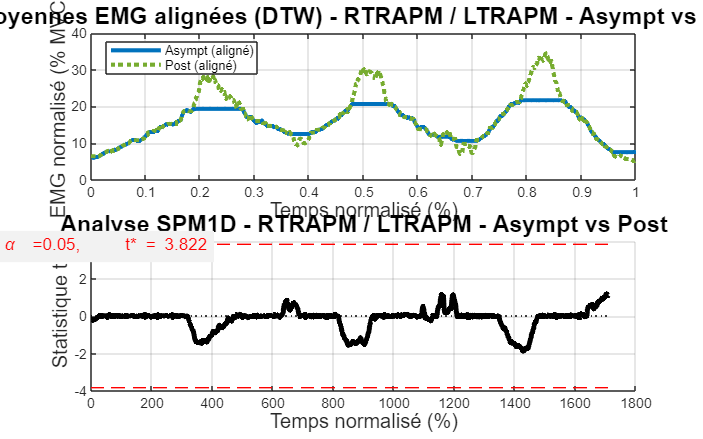

Alignement des courbes par DTW pour Pre vs Post...
Analyse SPM1D sur données alignées: Pre vs Post
Analyse SPM1D: Test apparié pour Pre vs Post


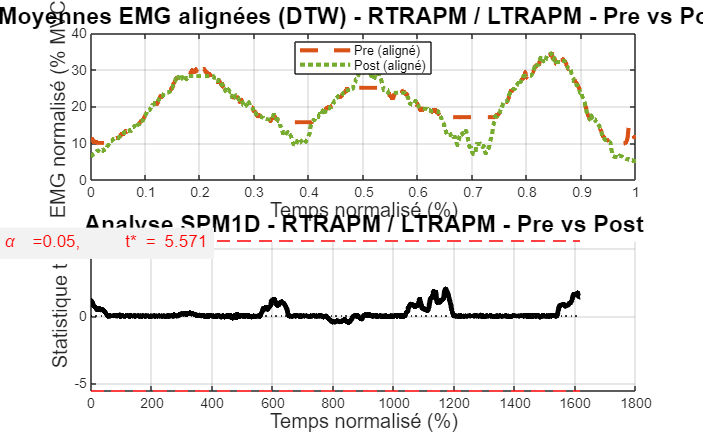

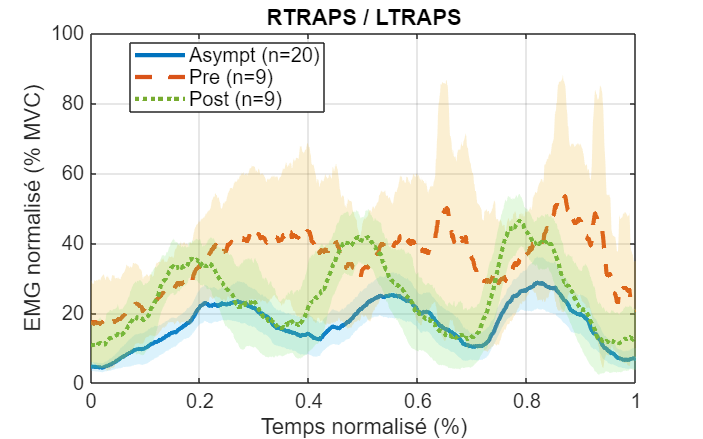

Alignement des courbes par DTW pour Asympt vs Pre...
Analyse SPM1D sur données alignées: Asympt vs Pre
Analyse SPM1D: Test indépendant pour Asympt vs Pre


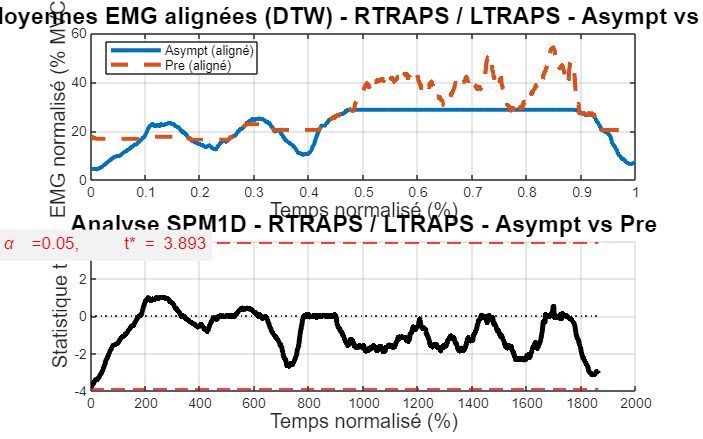

Alignement des courbes par DTW pour Asympt vs Post...
Analyse SPM1D sur données alignées: Asympt vs Post
Analyse SPM1D: Test indépendant pour Asympt vs Post


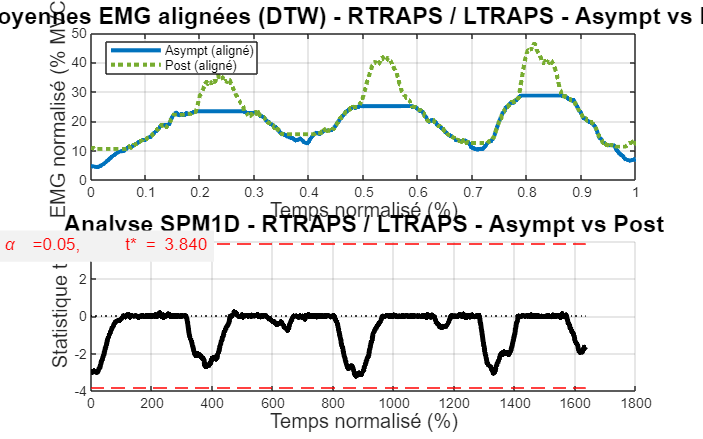

Alignement des courbes par DTW pour Pre vs Post...
Analyse SPM1D sur données alignées: Pre vs Post
Analyse SPM1D: Test apparié pour Pre vs Post


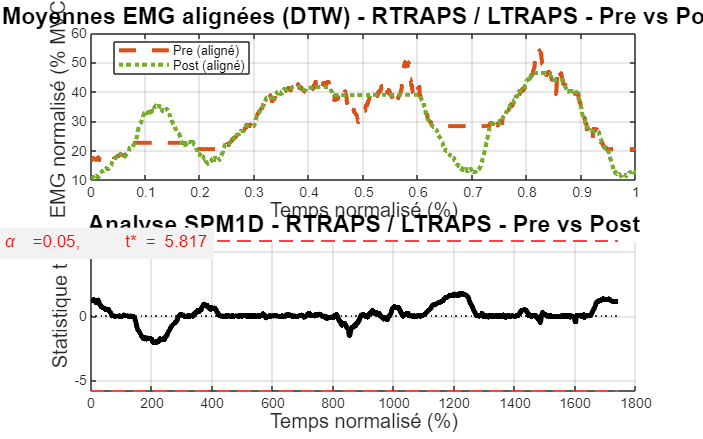

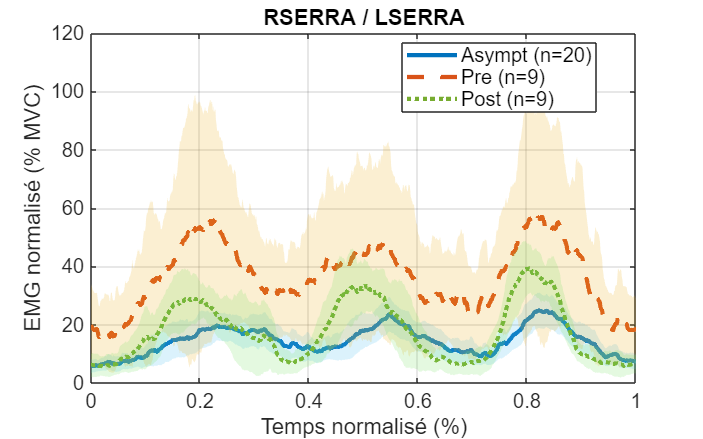

Alignement des courbes par DTW pour Asympt vs Pre...
Analyse SPM1D sur données alignées: Asympt vs Pre
Analyse SPM1D: Test indépendant pour Asympt vs Pre


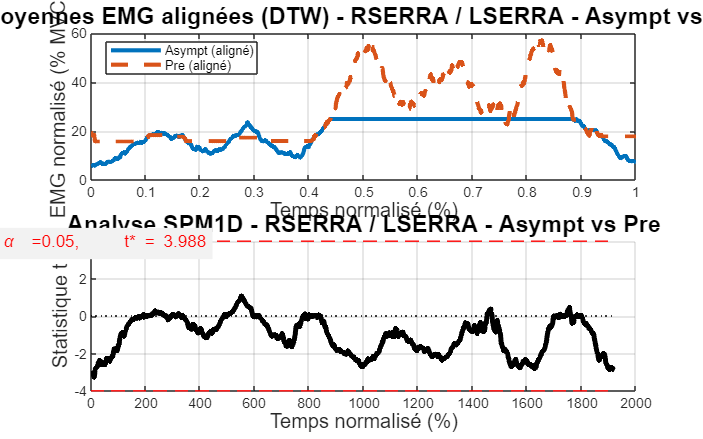

Alignement des courbes par DTW pour Asympt vs Post...
Analyse SPM1D sur données alignées: Asympt vs Post
Analyse SPM1D: Test indépendant pour Asympt vs Post


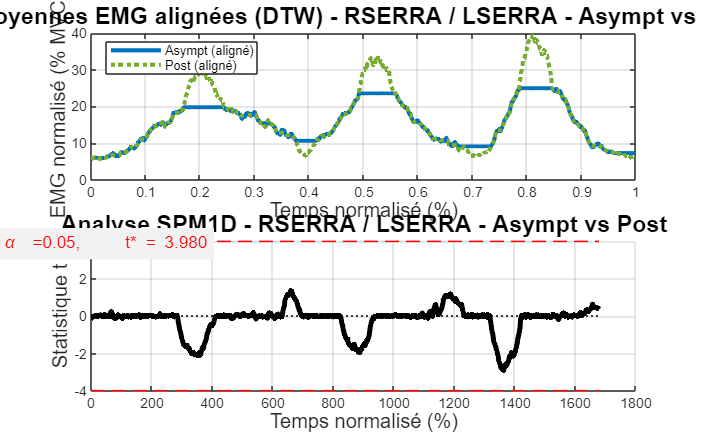

Alignement des courbes par DTW pour Pre vs Post...
Analyse SPM1D sur données alignées: Pre vs Post
Analyse SPM1D: Test apparié pour Pre vs Post


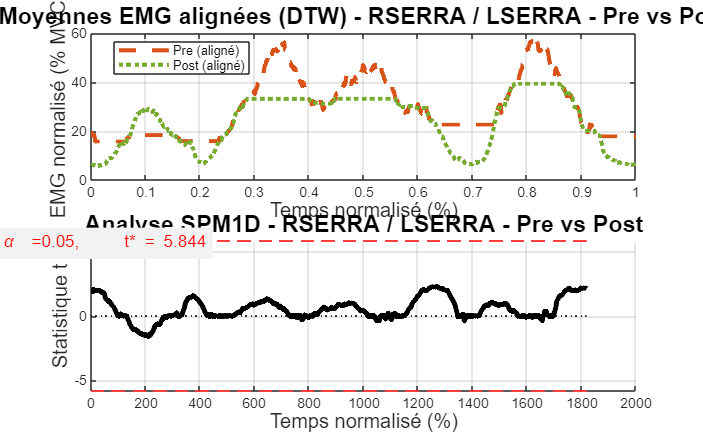


Tracé des profils EMG terminé. 6 figures créées.



% Exécuter la fonction principale avec SPM1D et DTW
plotCombinedEMGPerSubjectWithSPM1D(data_files, use_dtw);